# PhysioNet Challenge 2016: Classify normal and abnormal heart sounds

Live script demonstrating embedded data analytics workflow of heart sounds into 'Normal' and 'Abnormal' using machine learning

Add current folder and subfolders to search path

addpath(genpath(pwd))

## 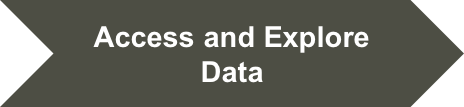

## What does an abnormal heart sound like?

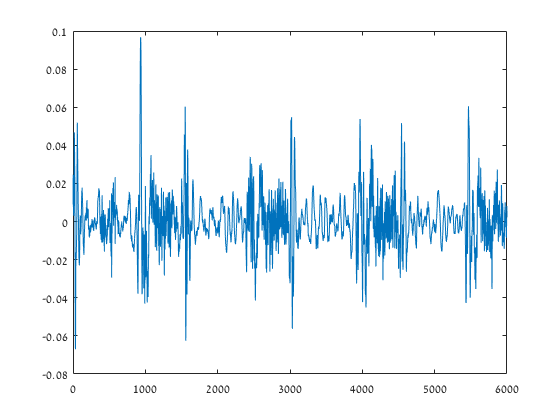

[PCG_abnormal, fs] = audioread('a0002_abnormal.wav');
p_abnormal = audioplayer(PCG_abnormal, fs);
play(p_abnormal, [1 (get(p_abnormal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_abnormal(1:fs*3))

## 

## What does a normal heart sound like?

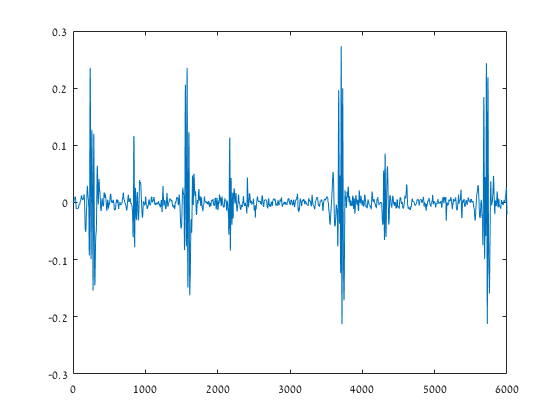

[PCG_normal, fs] = audioread('a0011_normal.wav');
p_normal = audioplayer(PCG_normal, fs);
play(p_normal, [1 (get(p_normal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_normal(1:fs*3))

## 

## What do the signals look like in the frequency domain?

Use the [Signal Analyzer](https://www.mathworks.com/help/signal/ug/getting-started-with-signal-analyzer-app.html) app to inspect and compare the power spectrum of the two signals.

signalAnalyzer(PCG_normal, PCG_abnormal)

## 

## Create a fileDatastore

Create a [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) with custom read function to handle large number of data files spread across multiple folders.

training_fds = fileDatastore(fullfile(pwd, 'Data', 'training'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav', 'IncludeSubfolders', 1);

## 

## Create a table with filenames and labels

Read .csv files with class labels and build a table with filename and corresponding label.

data_dir = fullfile(pwd, 'Data', 'training');
folder_list = dir([data_dir filesep 'training*']);

reference_table = table();

for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Normal, -1 = Abnormal
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

Processing files from folder: training-a
Processing files from folder: training-b
Processing files from folder: training-c
Processing files from folder: training-d
Processing files from folder: training-e
Processing files from folder: training-f


## 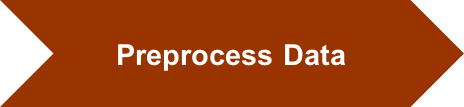

## Extract features from raw heart sound signals

Use statistical and signal processing functions available in MATLAB's toolboxes to process and extract features from the raw heart sound signal.

if ~exist('FeatureTable.mat','file')
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    
    % Distribute computation across available processors by using parfor
    parfor ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        
        % Extract features for the sub datastore
        feature_table = [feature_table; extractFeatures(subds, win_len, win_overlap, reference_table)];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');
else
    load('FeatureTable.mat');
end

% Take a look at the feature table
disp(feature_table(1:5,:))

     meanValue     medianValue    standardDeviation    meanAbsoluteDeviation    quantile25    quantile75    signalIQR    sampleSkewness    sampleKurtosis    signalEntropy    spectralEntropy    dominantFrequencyValue    dominantFrequencyMagnitude    dominantFrequencyRatio    WAVFEAT1     WAVFEAT2     WAVFEAT3     WAVFEAT4     WAVFEAT5    WAVFEAT6    WAVFEAT7    WAVFEAT8     WAVFEAT9     WAVFEAT10     WAVFEAT11     WAVFEAT12    WAVFEAT13     WAVFEAT14     WAVFEAT15     WAVFEAT16 

## 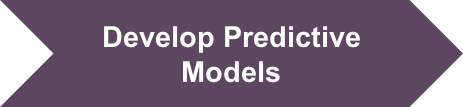

## Train, compare and select classifier 

Use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers.

classificationLearner

## 

## Split data into training and testing sets. 

Prepare the datasets for training and testing programmatically. Use [cvpartition](https://www.mathworks.com/help/stats/cvpartition.html) to split data into training and testing sets. Use [grpstats](https://www.mathworks.com/help/stats/grpstats.html) to tally number of observations for each class.

rng(1)
% Use 50% of data for training and remaining for testing
split_training_testing = cvpartition(feature_table.class, 'Holdout', 0.5);
 
% Create a training set
training_set = feature_table(split_training_testing.training, :);

% Create a validation set
testing_set = feature_table(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))

                GroupCount
                __________

    Abnormal    1579      
    Normal      4929      



## 

## Train the classifier with misclassification cost

Train the classifier programmatically. To compensate for fewer 'Abnormal' observations, assign higher misclassification cost with the 'Abnormal' class. Perform hyperparameter tuning by using [Bayesian Optimization](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html) to find optimal values for model parameters.

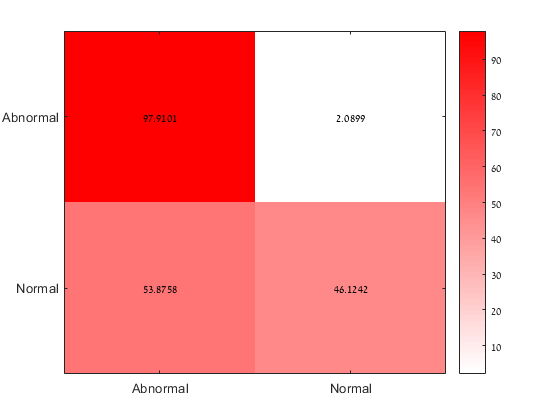

% Assign higher cost for misclassification of abnormal heart sounds
C = [0, 10; 1, 0];

% Create a random sub sample (to speed up training) from the training set
% subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
subsample = 1:height(training_set);

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

if ~exist('TrainedSVMModel.mat','file')
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
        'AcquisitionFunctionName','expected-improvement-plus');
    
    rng(1)
    trained_model = fitcsvm(training_set(subsample,:),'class','KernelFunction','rbf','Cost',C,...
        'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opts)
    save('TrainedSVMModel', 'trained_model');
else
    load('TrainedSVMModel.mat')
end

% Predict class labels for the validation set using trained model
predicted_class = predict(trained_model, testing_set);

conf_mat = confusionmat(testing_set.class, predicted_class);

conf_mat_per = conf_mat*100./sum(conf_mat, 2);

% Visualize model performance
labels = {'Abnormal', 'Normal'};
heatmap(conf_mat_per, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);

## 

## Perform feature selection using Neighborhood Componant Analysis

Use [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) to select a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features.

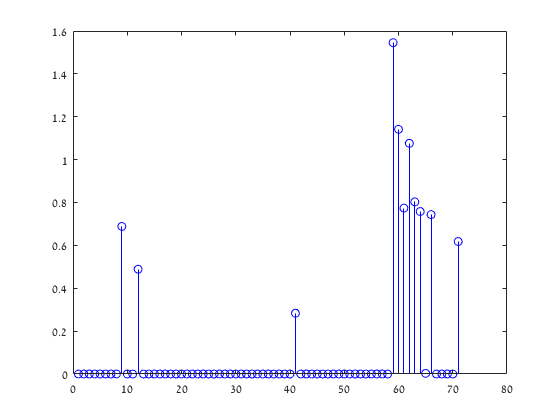

% Perform feature selection with neighborhood component feature selection
rng(1)
mdl = fscnca(table2array(training_set(:,1:71)), ...
    table2array(training_set(:,72)), 'Lambda', 0.005, 'Verbose', 0);

% Select features with weight above 1
selected_feature_indx = find(mdl.FeatureWeights > 0.1);

% Plot feature weights
stem(mdl.FeatureWeights,'bo');


% Load saved array of selected feature indexes to ensure reproducibility
load('SelectedFeatures.mat')

% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

  Columns 1 through 9

    'sampleKurtosis'    'dominantFrequency…'    'MFCC1'    'MFCC2'    'MFCC3'    'MFCC4'    'MFCC5'    'MFCC6'    'MFCC7'

  Columns 10 through 11

    'MFCC10'    'MFCC13'



## 

## Train model with selected features

Train model using only selected features and find optimal hyperparameter values to produce the final model for deployment.

if ~exist('TrainedSVMModel_FeatSel.mat','file')
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
        'AcquisitionFunctionName','expected-improvement-plus');
    
    rng(1)
    trained_model_featsel = fitcsvm(training_set(subsample,selected_feature_indx),training_set.class(subsample),'KernelFunction','rbf','Cost',C,...
        'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opts)
    save('TrainedSVMModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedSVMModel_FeatSel.mat')
end

% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, testing_set(:,selected_feature_indx));

Undefined function or variable 'testing_set'.


conf_mat_featsel = confusionmat(testing_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'Abnormal', 'Normal'};

% Visualize model performance
heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);

## 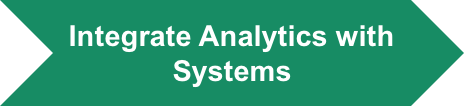

## Code Generation

Generate C code that takes recorded signal and sampling frequency as input and produces heart sound classification label as output.

% Save trained model as a compact model for code generation
saveCompactModel(trained_model_featsel,'HeartSoundClassificationModel');

% Open entry point function for code generation
open classifyHeartSounds.m

% Use the coder app to generate C code by following a step-by-step process
% Make sure to turn off report generation. 
% classifyHeartSounds(PCG_abnormal, fs) %copy for use in Coder
coder

## Validate final model

Process audio files from the validation set with model produced by MATLAB coder.

plotPredictions

Invalid MEX-file 'C:\Users\shirang\Documents\Seminars\סמינר למידת מכונה - 6-7.2.17\HeartSoundsClassification\classifyHeartSounds_mex.mexw64': 
Missing symbol '?to_ustring@i18n@fl@@YA?AV?$basic_string@_WU?$char_traits@_W@std@@V?$allocator@_W@2@@std@@PEBD@Z' in 'C:\Program Files\MATLAB\R2017b/bin/win64\libmwi18n.dll' required by 'C:\Users\shirang\Documents\Seminars\סמינר למידת מכונה - 6-7.2.17\HeartSoundsClassification\classifyHeartSounds_mex.mexw64'.

Error in plotPredictions (line 35)
    predicted{i} = classifyHeartSounds_mex(signal, fs);